# BPSK system model

Configure Input parameters:

1 - Number of data bits to transfer

2 - Signal-to-noise ratio (dB) in the channel - determined by AWGN level

3 - Carrier frequency (Hz)

fprintf("\nInput parameters:\n")


Input parameters:


% Data bit sequence lengths
num_data_bits = [16, 64] ;
fprintf(['Data bit sequence lengths =' repmat(' %d',1,numel(num_data_bits))], num_data_bits)

Data bit sequence lengths = 16 64

fprintf("\n")

% SNR (dB) range
SNR = -5: 5: 5;
fprintf(['SNR (dB) =' repmat(' %.1f',1,numel(SNR))], SNR)

SNR (dB) = -5.0 0.0 5.0

fprintf("\n")

% Carrier frequency (Hz)
F_carrier = 1000;
fprintf("Carrier frequency (Hz) = %d", F_carrier)

Carrier frequency (Hz) = 1000

fprintf("\n")

## Each loop iteration models another BPSK system defined by input parameters


* BPSK simulation *
Number of data bits: 16 
SNR (dB): -5.0 


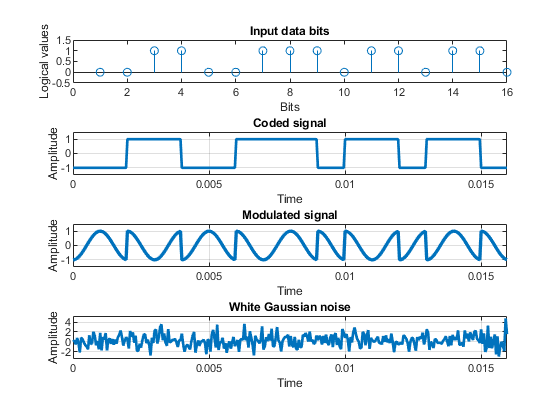

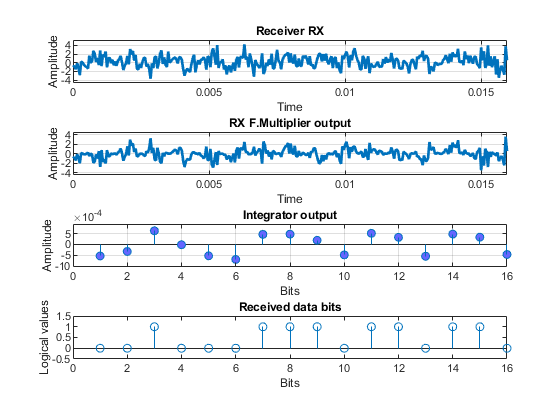


* BPSK simulation *
Number of data bits: 16 
SNR (dB): 0.0 


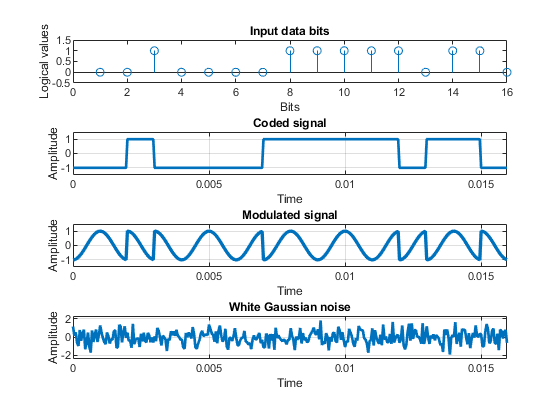

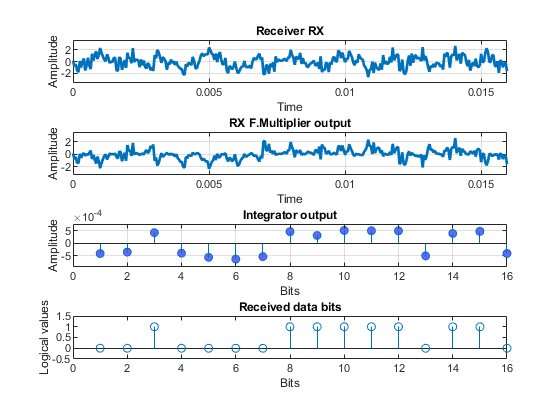


* BPSK simulation *
Number of data bits: 16 
SNR (dB): 5.0 


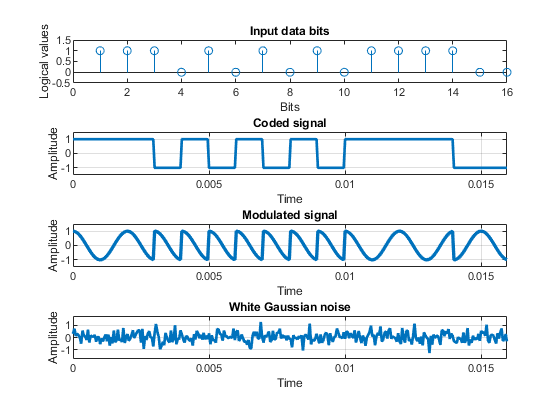

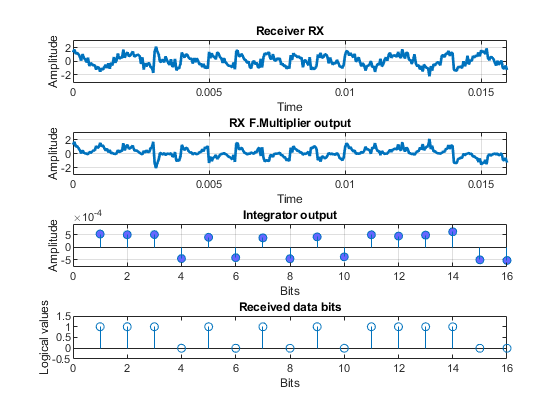


* BPSK simulation *
Number of data bits: 64 
SNR (dB): -5.0 


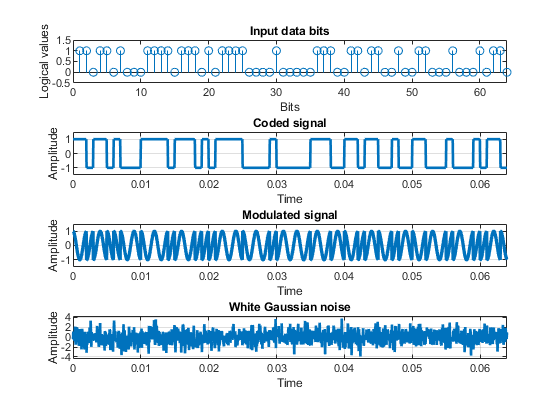

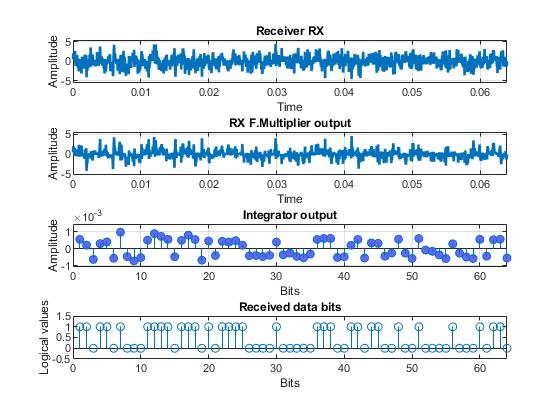


* BPSK simulation *
Number of data bits: 64 
SNR (dB): 0.0 


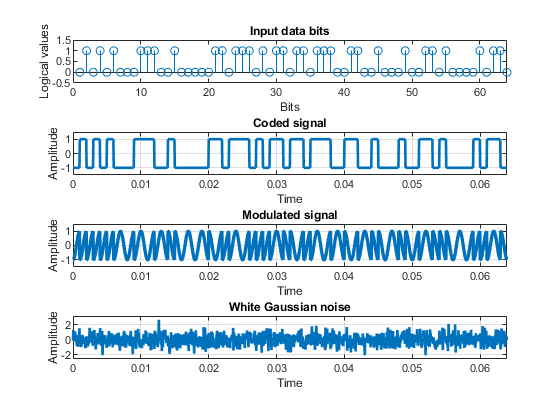

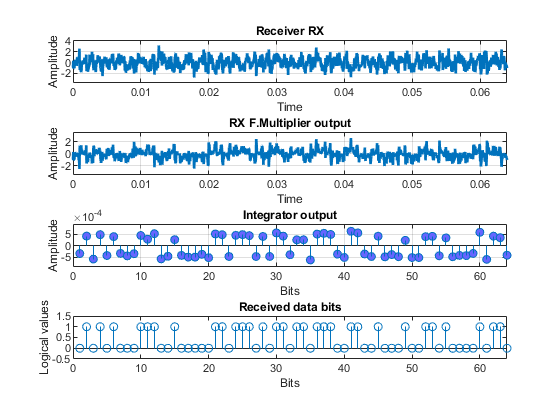


* BPSK simulation *
Number of data bits: 64 
SNR (dB): 5.0 


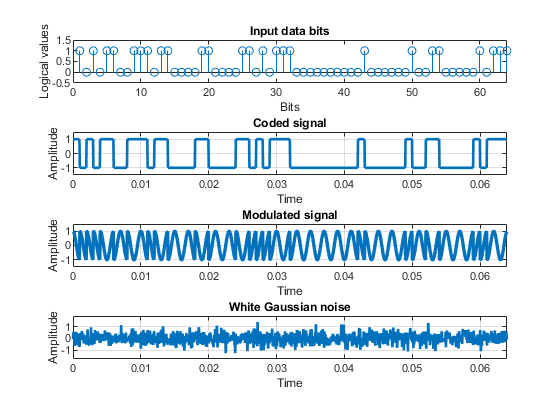

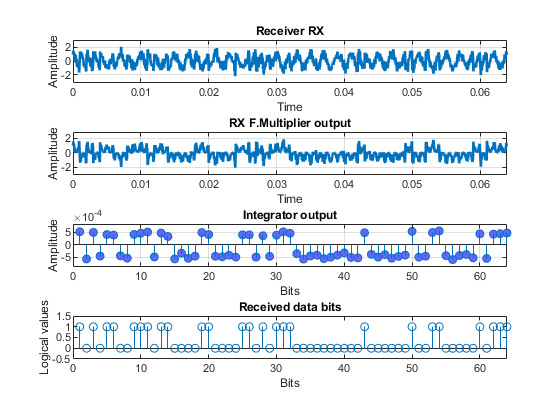

% LOOP
for iter1 = 1 : length(num_data_bits)
    for iter2 = 1 : length(SNR)
        if(iter1 == 1 && iter2 == 1)
            close_figs = true;
        else
            close_figs = false;
        end
        [data_bits, time, Ts, Tb, bpsk_coded_signal, Carrier] = ...
            bpsk_init(num_data_bits(iter1), SNR(iter2), 500, close_figs, true);
        %------------------------------------------------------------
        % Transmitter TX - Frequency multiplier
        % Frequency multiplier output
        bpsk_modulated_signal = bpsk_coded_signal .* Carrier; 
        %---------------------------------------------------------------
        % Line/channel 
        EbN0 = 10^(SNR(iter2)/10); % 
        AWGN_sigma = sqrt(1/(EbN0*2));
        AWGN = AWGN_sigma * randn(1, length(bpsk_modulated_signal));
        %---------------------------------------------------------------
        % Adding Gaussian noise:
        received_signal = bpsk_modulated_signal + AWGN; 
        %---------------------------------------------------------------
        signal_time_plots(['Input Signals' ' ' num2str(iter1) ' ' num2str(iter2)], ...
            time, data_bits, bpsk_coded_signal, bpsk_modulated_signal, AWGN);

        %---------------------------------------------------------------
        % Receiver RX - Frequency multiplier (synchronous demodulation)
        Rx_fmultiplier_output = received_signal .* Carrier; 
        %---------------------------------------------------------------
        % Receiver RX - Integrator
        interval = 0 : Ts : Tb-Ts; 
        % integration boundaries define Tb (data bit duration)
        Integrator_output = zeros(1,(length(Rx_fmultiplier_output)/(Tb/Ts)));
        % (length(Rx_fmultiplier_output)/(Tb/Ts)) == num_data_bits
        for i = 0 : (length(Rx_fmultiplier_output)/(Tb/Ts))-1  % num of bits
             Integrator_output(i+1) = trapz(interval, ...
                 Rx_fmultiplier_output( (i*(Tb/Ts)+1) : ((i+1)*(Tb/Ts))) );
        end
        % trapz does numerical integration using trapezoidal method
        % on data bit duration interval
        %------------------------------------------------------------
        % Receiver RX - decision making using Treshold
        % 0 is Treshold, decision: 0 for -1, 1 for 1
        Decider_output = (Integrator_output >= 0); 
        % Decider_output yealds received data bits
        %------------------------------------------------------------
        signal_time_plots(['Output Signals' ' ' num2str(iter1) ' ' num2str(iter2)], ...
            time, received_signal, Rx_fmultiplier_output, Integrator_output, Decider_output);
    end
end